# Parametric Curves 

A more general representation of a curve involves expressing its coordinates in terms of another independent variable or parameter as follows


$$x = f(u), y = g(u), u \in [a,b]$$


Each value of u corresponds to a coordinate pair (f(u), g(u)). If we collect all the points defined by u in a specific interval, we get a parametric curve. For example, the definition


$$x = \cos u, y = \sin u, u \in [0, 2 \pi]$$


defines a unit circle, centered at the origin, which begins and ends at (1,0).

In order to visualize a parametric curve in Matlab, we first define a set of points on the u-domain.

u = linspace(0,2*pi,100)

u =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


Next we define a function that accepts as u as input, and returns the coordinates x and y as output. The function is defined at the end of this script, but we include it here for clarity

**function [x,y] = circle(u)**

**    x = cos(u)**

**    y = sin(u)**

**end**

Now with the function defined, we can call it and then use **plot** as before, setting the axes so that it is clear that we have a circle.

[x,y] = circle(u)

x =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995


y =          0    0.0634    0.1266    0.1893    0.2511    0.3120    0.3717    0.4298    0.4862    0.5406    0.5929    0.6428    0.6901    0.7346    0.7761    0.8146    0.8497    0.8815    0.9096    0.9341    0.9549    0.9718    0.9848    0.9938    0.9989    0.9999    0.9969    0.9898    0.9788    0.9638    0.9450    0.9224    0.8960    0.8660    0.8326    0.7958    0.7557    0.7127    0.6668    0.6182    0.5671    0.5137    0.4582    0.4009    0.3420    0.2817    0.2203    0.1580    0.0951    0.0317


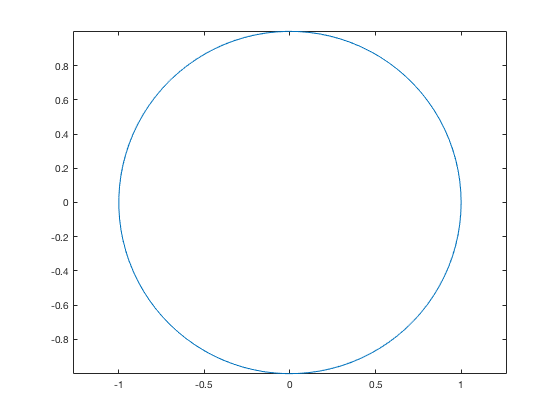

plot(x,y)
axis equal

As u increases from 0 to $2\pi$, the circle is traced out in counter-clockwise direction. The variable u can be interpreted as the angle from the x-axis to the current point on the circle.

**Exercise 1:** Look up the parametric equations that define an ellipse, and use the techniques developed here to visualize them. 

Solution: A quick browse of the internet shows that the parametric equations for an ellipse are


$$x = a \cos u, y = b \sin u, u \in [0,2\pi]$$


where a and b are parameters. Let's visualize the ellipse corresponding to a = 1 and b = 2

[x,y] = ellipse(1,2,u)

x =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995


y =          0    0.1268    0.2532    0.3785    0.5023    0.6241    0.7433    0.8596    0.9724    1.0813    1.1858    1.2856    1.3802    1.4692    1.5523    1.6292    1.6995    1.7629    1.8193    1.8683    1.9098    1.9436    1.9696    1.9877    1.9977    1.9997    1.9937    1.9796    1.9576    1.9277    1.8900    1.8447    1.7920    1.7321    1.6651    1.5915    1.5115    1.4254    1.3335    1.2363    1.1341    1.0274    0.9165    0.8019    0.6840    0.5635    0.4406    0.3160    0.1901    0.0635


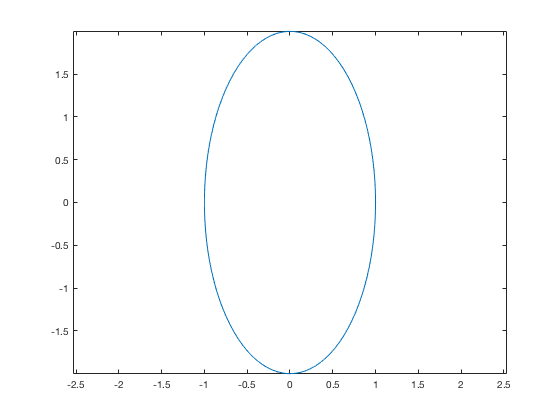

plot(x,y)
axis equal

**Exercise 2:** A helix in 3D is often defined using the parametric equations


$$x = a \cos u, y = a \sin u, z = bu$$


where both a and b are positive. Use **plot3** to visualize the helix with a = 1 and b = 2 over the domain $u \in [0,10]$.

[x,y,z] = helix(1,2,0:0.1:10)

x =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


y =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


z =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


x =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


y =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


z =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


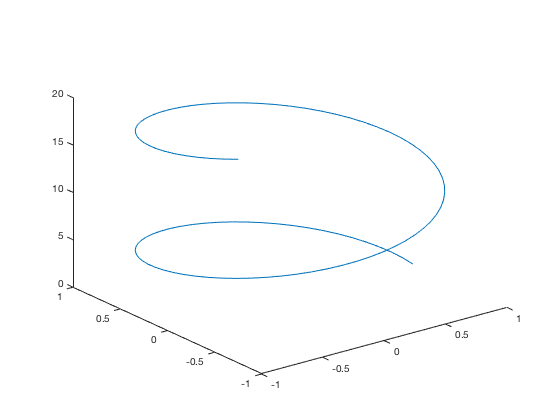

plot3(x,y,z)

## Function definitions

function [x,y] = circle(u)
    % circle   Computes the coordinates of a parametric circle
    x = cos(u);
    y = sin(u);
end

function [x,y] = ellipse(a,b,u)
    x = a*cos(u);
    y = b*sin(u);
end

function [x,y,z] = helix(a,b,u)
    x = a*cos(u)
    y = a*sin(u)
    z = b*u
end